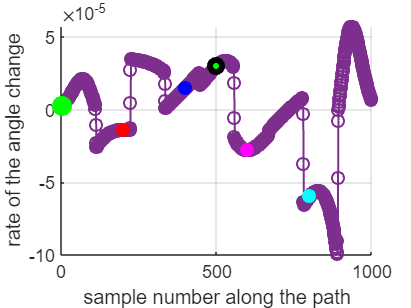

% DEEMED UNNECESSARY
% Though I would like to include it, to show that I did consider
% other alternatives to finding data that would best suit my calculations

% Lake Etsitty, MENG 451
% This is as the title reads, calculating the derivative 

B = [ 1:length(phirad) ; phirad];
avg_change_of_angle = zeros(1,length(B)-2);

for i = 2:(length(B)-1)
    x3 = B(1,(i-1):(i))';
    y3 = B(2,(i-1):(i))';
    
    c3 = [[1; 1]  x3]\y3;   

    slope3 = c3(2);
    
    x4 = B(1,i:i+1)';
    y4 = B(2,i:i+1)';
    c4 = [[1; 1] x4]\y4;  

    slope4 = c4(2);

    avg_change_of_angle(1,i-1) = (slope4+slope3)/2;
end


figure
hold all
plot(4:length(avg_change_of_angle)+3, avg_change_of_angle,'-o','linewidth',1,'Color',[0.4940, 0.1840, 0.5560])
grid on
xlabel('sample number along the path')
ylabel('rate of the angle change')
title('Objective 3')
plot(4,avg_change_of_angle(1),'o','linewidth',4,"MarkerFaceColor",'g',"MarkerEdgeColor",'g')

plot(pos02,avg_change_of_angle(1,pos02),'o','linewidth',1,"MarkerFaceColor",'r',"MarkerEdgeColor",'r')
plot(pos04,avg_change_of_angle(1,pos04),'o','linewidth',1,"MarkerFaceColor",'b',"MarkerEdgeColor",'b')
plot(pos05,avg_change_of_angle(1,pos05),'o','linewidth',3,"MarkerFaceColor",'g',"MarkerEdgeColor",'k')
plot(pos06,avg_change_of_angle(1,pos06),'o','linewidth',1,"MarkerFaceColor",'m',"MarkerEdgeColor",'m')
plot(pos08,avg_change_of_angle(1,pos08),'o','linewidth',1,"MarkerFaceColor",'c',"MarkerEdgeColor",'c')

hold off

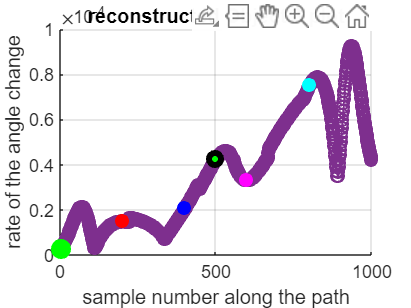


% The following section was made to take away 
% the breaks in the previous plot

for i = 2:length(avg_change_of_angle)
    sloep = avg_change_of_angle(i)-avg_change_of_angle(i-1);

    % Play with this to take away the breaks in the previous plot
    if abs(sloep) > 0.000002

        avg_change_of_angle(i:end) = avg_change_of_angle(i:end) - sloep;
    else
        avg_change_of_angle(i:end) = avg_change_of_angle(i:end);
    end
end


figure 
hold all

grid on
title('reconstructed Object 3 plot')
plot(4:length(avg_change_of_angle)+3, avg_change_of_angle,'-o','linewidth',1,'Color',[0.4940, 0.1840, 0.5560])
grid on
xlabel('sample number along the path')
ylabel('rate of the angle change')

plot(4,avg_change_of_angle(1),'o','linewidth',4,"MarkerFaceColor",'g',"MarkerEdgeColor",'g')
plot(pos02,avg_change_of_angle(1,pos02),'o','linewidth',1,"MarkerFaceColor",'r',"MarkerEdgeColor",'r')
plot(pos04,avg_change_of_angle(1,pos04),'o','linewidth',1,"MarkerFaceColor",'b',"MarkerEdgeColor",'b')
plot(pos05,avg_change_of_angle(1,pos05),'o','linewidth',3,"MarkerFaceColor",'g',"MarkerEdgeColor",'k')
plot(pos06,avg_change_of_angle(1,pos06),'o','linewidth',1,"MarkerFaceColor",'m',"MarkerEdgeColor",'m')
plot(pos08,avg_change_of_angle(1,pos08),'o','linewidth',1,"MarkerFaceColor",'c',"MarkerEdgeColor",'c')